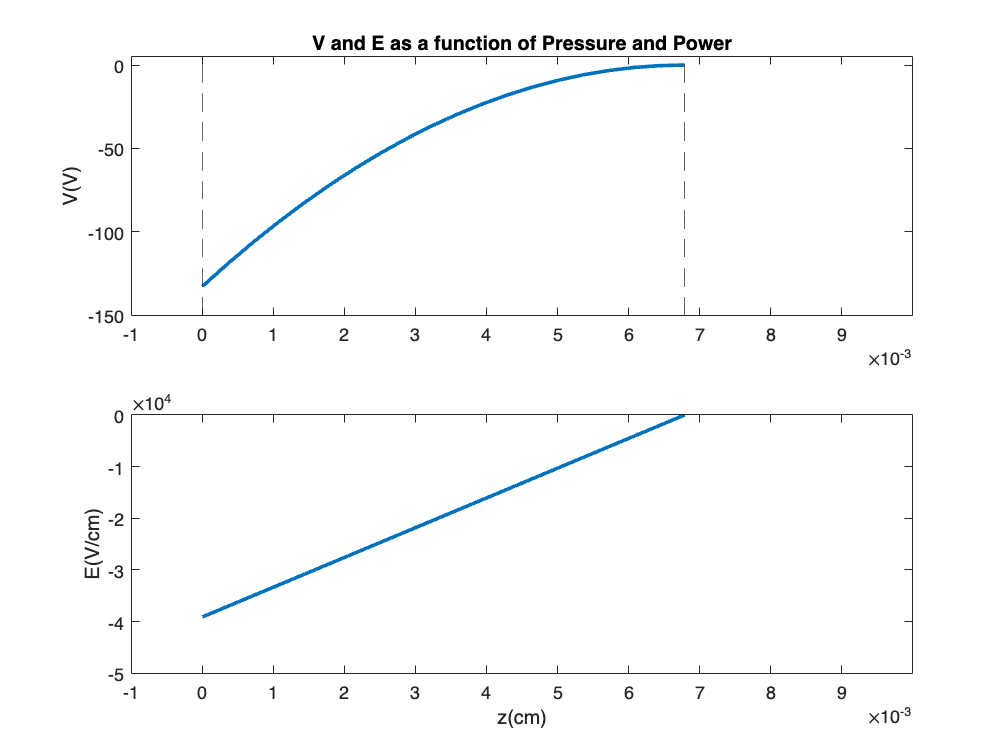

load ../data/LUTData.mat
LUT = LUTArray{2};

% Declare data
pressure = LUT.Pressure;
power = LUT.Power;

% Configure pressure slider
minPressure = min(pressure,[],'all');
maxPressure = max(pressure,[],'all');
stepPressure = (maxPressure-minPressure)/100;

% Configure power slider
minPower = min(power,[],'all');
maxPower = max(power,[],'all');
stepPower = (maxPower-minPower)/100;


currPressure =1.17;
currPower =24.6;

% Interpolate values
z0 = interp2(pressure,power,LUT.SheathHeight,currPressure,currPower,'linear');
b0 = interp2(pressure,power,LUT.Beta,currPressure,currPower,'linear');

z = linspace(0,z0,20);
V = parabola(z,b0,z0);

% Calculate electric field
E = -2*b0*(z-z0);
zRange = [-1 10] * 1e-3;

subplot(2,1,1)
plot(z,V,'LineWidth',2)
xline([0 z0],'--');
text([-.2 (z0-.2)],[0.5 0.5]*(-150),{{'h_0=0'},{sprintf("h_s=%.1fcm",z0)}},'Rotation',90);

title('V and E as a function of Pressure and Power')
ylabel('V(V)')
ylim([-150 5])
xlim(zRange)

subplot(2,1,2)
plot(z,E,'LineWidth',2)

ylabel('E(V/cm)')
xlabel('z(cm)')
xlim(zRange)
ylim([-50 0] * 1e3)

function y = parabola(z,b0,z0)
    y = b0 * (z-z0).^2;
end